## Matrixes product order is not conmutative

% Performing rotation in X-Y-Z order
R = rotz(90)*roty(180)*rotx(90);
T = HTM(R)

T =      0     0     1     0
    -1     0     0     0
     0    -1     0     0
     0     0     0     1



% Performing rotation in Z-Y-X order
R = rotx(90)*roty(180)*rotz(90);
T = HTM(R)

T =      0     1     0     0
     0     0     1     0
     1     0     0     0
     0     0     0     1


R = rotx(90)*roty(180);
p = [10 5 0]';

T1 = HTM(R);
T2 = HTM(eye(3,3), p);

% Performing traslation followed by rotation
T = T1*T2

T =     -1     0     0   -10
     0     0     1     0
     0     1     0     5
     0     0     0     1



% Performing rotation followed by traslation
T = T2*T1

T =     -1     0     0    10
     0     0     1     5
     0     1     0     0
     0     0     0     1


## Solving for vector **r**

p = [6 -3 8]';
T = HTM(eye(3,3), p);

ruvw = [-2 7 3 1]';

% Calculating vector r coordinates from UVW to XYZ system
rxyz = T*ruvw

rxyz =      4
     4
    11
     1



% Calculating new vector r coordinates in XYZ system
rxyz_prime = T*rxyz

rxyz_prime =     10
     1
    19
     1


R = rotx(90);
p = [8 -4 12]';

% Performing rotation followed by traslation
T = HTM(eye(3,3), p)*HTM(R)

T =      1     0     0     8
     0     0    -1    -4
     0     1     0    12
     0     0     0     1



ruvw = [-3 4 -11 1]';

% Calculating vector r coordinates from UVW to XYZ system
rxyz = T*ruvw

rxyz =      5
     7
    16
     1



% Performing traslation followed by rotation
T = HTM(R)*HTM(eye(3,3), p)

T =      1     0     0     8
     0     0    -1   -12
     0     1     0    -4
     0     0     0     1



% Calculating vector r coordinates from UVW to XYZ system
rxyz = T*ruvw

rxyz =      5
    -1
     0
     1


## Homogeneous Matrixes Composition

% Performing rotx(-90) - pxyz(5 5 10) - rotz(90)
R1 = rotx(-90);
pxyz = [5 5 10]';
R2 = rotz(90);

% Performing operations using XYZ fixed system as reference
T = HTM(R2) * HTM(eye(3), pxyz) * HTM(R1)

T =      0     0    -1    -5
     1     0     0     5
     0    -1     0    10
     0     0     0     1


% Performing pxyz(-3 10 10) - rotu(-90) - rotv(90)
pxyz = [-3 10 10]';
R1 = rotx(-90);
R2 = rotz(90);

% Performing operations using UVW system as reference
T = HTM(eye(3), pxyz) * HTM(R1) * HTM(R2)

T =      0    -1     0    -3
     0     0     1    10
    -1     0     0    10
     0     0     0     1


% 1. If XYZ and UVW systems are identical, the homogeneous
% transformation matrix will be a 4x4 intity matrix
%
% 2. If UVW is obtained by rotation/translation using XYZ fixed system,
% the homogeneous matrix that represents every transformation will have
% to premultiply following the inverse order
%
% 3. If UVW is obtained by rotation/translation using a movile system,
% the homogeneous matrix that represents every transformation will have
% to postmultiply following the same order

R = rotz(90)*roty(180)*rotx(90);
T = HTM(R)

T =      0     0     1     0
    -1     0     0     0
     0    -1     0     0
     0     0     0     1



% Rotating in X-Y-Z order using XYZ fixed system as reference
% or
% Rotating in W-V-U order using UVW system as reference

## Transformation Graphs

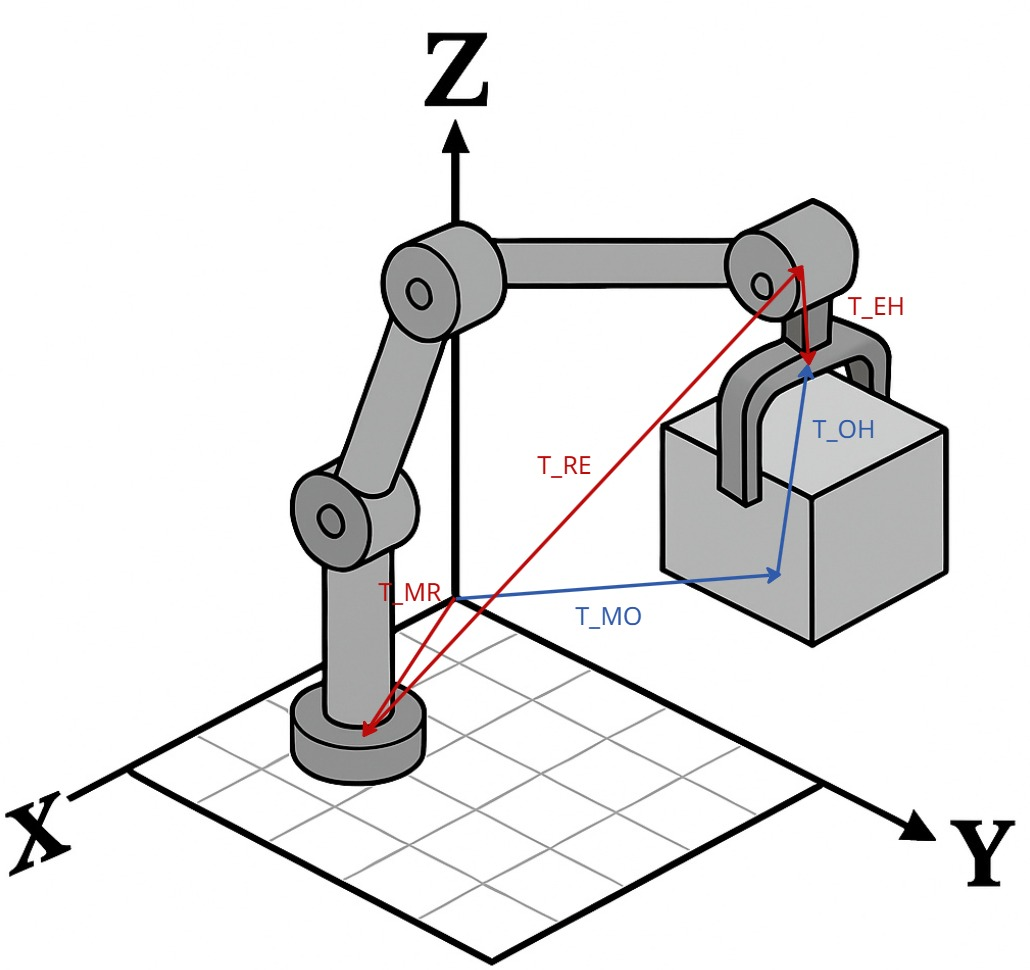

% Not applying rotation to keep it simple

% Origin - Manipulator's Base
T_MR = HTM(eye(3), ([3 1 0]'));
% Manipulator's Base - Final Actuator's Base
T_RE = HTM(eye(3), ([-1 5 10]'));
% Final Actuator's Base - Final Actuator's Tip
T_EH = HTM(eye(3), ([0 0 -1]'));

% Origin - Object
T_MO = HTM(eye(3), ([2 6 8]'));
% Object - Final Actuator's Tip
T_OH = HTM(eye(3), ([0 0 1]'));

% The Final Actuator's Tip can be refered with respect to the XYZ fixed
% system in two different ways.
T1 = T_MR * T_RE * T_EH

T1 =      1     0     0     2
     0     1     0     6
     0     0     1     9
     0     0     0     1


T2 = T_MO * T_OH

T2 =      1     0     0     2
     0     1     0     6
     0     0     1     9
     0     0     0     1



all(all( T1 == T2 ))

ans = logical
   1


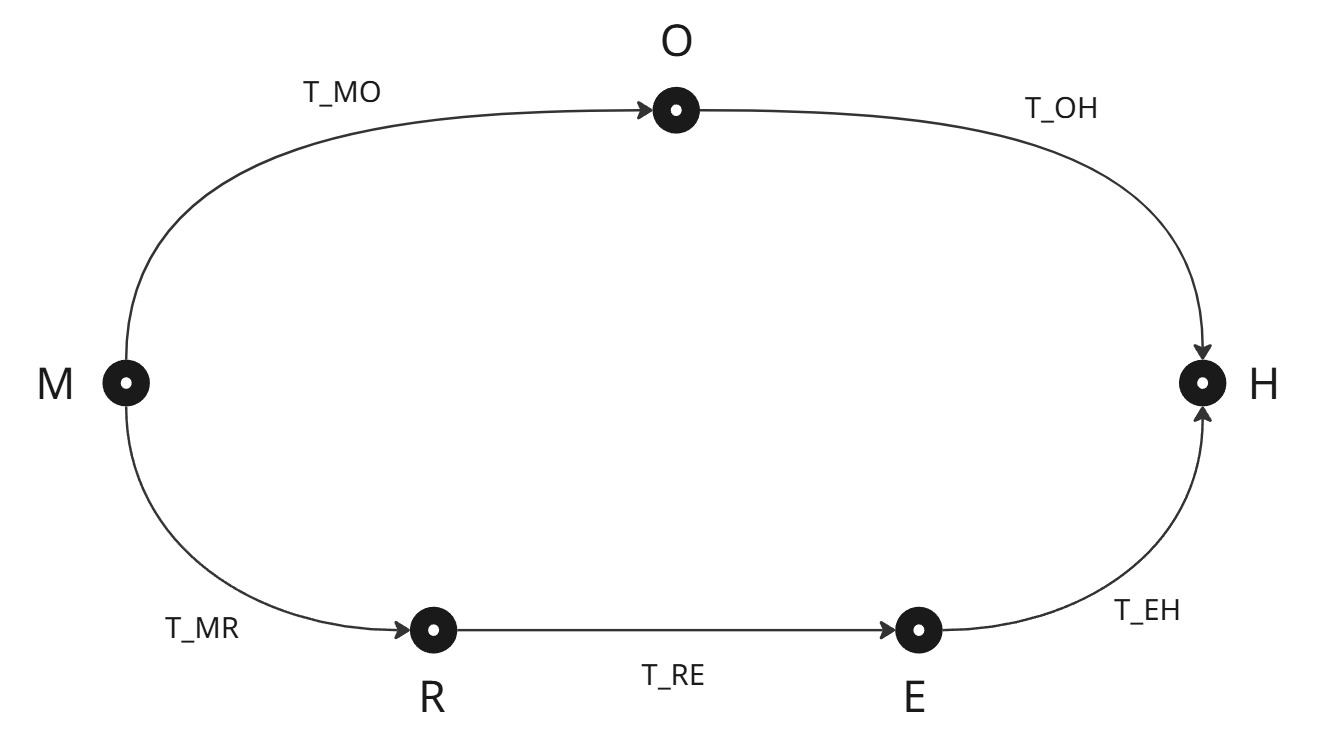

% The relationship between the object and the final actuator's tip
T1 = T_MR * T_RE * T_EH * T_MO^(-1)

T1 =      1     0     0     0
     0     1     0     0
     0     0     1     1
     0     0     0     1


T2 = T_OH

T2 =      1     0     0     0
     0     1     0     0
     0     0     1     1
     0     0     0     1



all(all( T1 == T2 ))

ans = logical
   1



% The relationship between the manipulator's base and the object
T1 = T_RE * T_EH * T_OH^(-1)

T1 =      1     0     0    -1
     0     1     0     5
     0     0     1     8
     0     0     0     1


T2 = T_MO * T_MR^(-1)

T2 =      1     0     0    -1
     0     1     0     5
     0     0     1     8
     0     0     0     1



all(all( T1 == T2 ))

ans = logical
   1


## Quaternion Operations